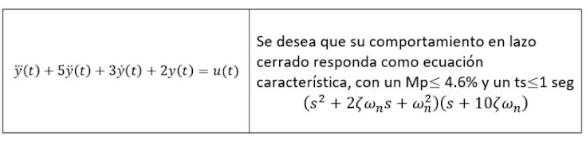

clc
clear
%Hallamos funcion de transferencia
s=tf('s');
G=1/(s^3+5*s^2+3*s+2)

G =
 
            1
  ---------------------
  s^3 + 5 s^2 + 3 s + 2
 
Continuous-time transfer function.
Model Properties


stepinfo(G)

ans = struct with fields:
         RiseTime: 2.2868
    TransientTime: 12.7039
     SettlingTime: 12.7039
      SettlingMin: 0.4501
      SettlingMax: 0.6114
        Overshoot: 22.2770
       Undershoot: 0
             Peak: 0.6114
         PeakTime: 5.4374



Ge=ss(G)
A=Ge.a; B=Ge.b;C=Ge.c;D=Ge.d; %Separamos nuestras matrices
%A=[-5 -1.5 -1;2 0 0;0 1 0] %Matriz A sin controlar
%B=[0.5;0;0]                %Matriz b sin controlar
%C=[0 0 1]                  %MAtriz c sin controlar
Mc=ctrb(A,B); %%matriz de controlabilidad
rank(Mc) 

%Establecemos parametros para hallar polos deseados
mp=0.046;
ts=1;
zeta=-log(mp)/(sqrt(pi^2+log(mp)^2))

zeta = 0.7070

wn=4/(zeta*ts) %% criterio del 2%

wn = 5.6577

sigma=zeta*wn

sigma = 4.0000

wd=wn*sqrt(1-zeta^2)

wd = 4.0012

sx=-sigma+wd*i

sx = 4.0000 + 4.0012i


P=[sx conj(sx)]

P =   -4.0000 + 4.0012i  -4.0000 - 4.0012i


P=[sx conj(sx) -20] %Agregamos un tercer polo 10 veces mas lejos

A =     -3    -1
     1     0


B =      1
     0


C =      0     2


D = 0

% [A,B,C,D]=tf2ss(2,[1 3 1])


ans = 2

K=acker(A,B,P) %%vector de ganancia

K =     5.0000   31.0096


Alc=A-B*K; %%matriz de estado en lazo cerrado
%Validacion
Gc=ss(Alc,B,C,0) %%FT CONTROLADA

Gc =
 
  A = 
           x1      x2
   x1      -8  -32.01
   x2       1       0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   2
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


GC1=tf(Gc)

GC1 =
 
          2
  -----------------
  s^2 + 8 s + 32.01
 
Continuous-time transfer function.
Model Properties


stepinfo(GC1)

ans = struct with fields:
         RiseTime: 0.3798
    TransientTime: 1.0540
     SettlingTime: 1.0540
      SettlingMin: 0.0565
      SettlingMax: 0.0652
        Overshoot: 4.3251
       Undershoot: 0
             Peak: 0.0652
         PeakTime: 0.7829


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -4.00e+00 + 4.00e+00i     7.07e-01       5.66e+00         2.50e-01    
 -4.00e+00 - 4.00e+00i     7.07e-01       5.66e+00         2.50e-01    



F=1/dcgain(Gc) %%PREFILTRO para reducir el error en estado estacionario

F = 16.0048

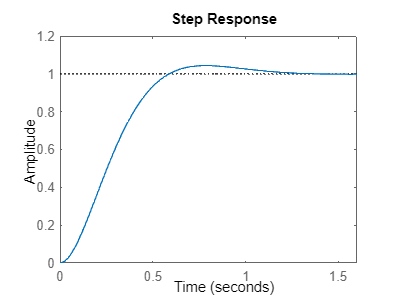


step(F*Gc)